% uncomment one you want to test and run to test
% filename = "CrossStep\crossstep3.mat"
% filename = "180Step\180step2.mat"
% filename = "PeterPan\peterpan3.mat"
filename = "Push\push5.mat"

filename = "Push\push5.mat"

% process data
[MotionData]=ParseMatlabApp(filename);
t = MotionData.t_Accel; 
accel = MotionData.Accel;

secondsToTrim = 5;
[t, accel] = trim_accel_data(t, accel, secondsToTrim);

Fs = 50;    
reduction_range = 0.1;
ax = reduce_gravity(moving_avg(accel(:,1)), Fs, reduction_range);
ay = reduce_gravity(moving_avg(accel(:,2)), Fs, reduction_range);
az = reduce_gravity(moving_avg(accel(:,3)), Fs, reduction_range);

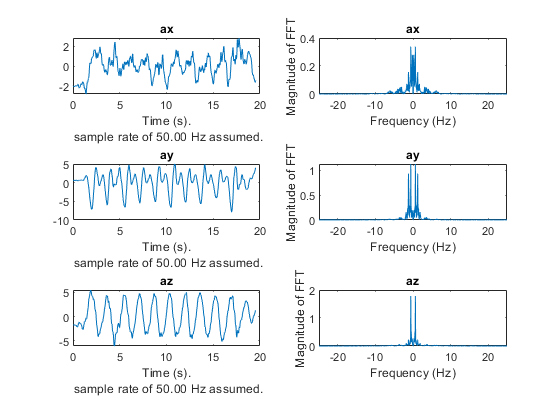

% create plot
figure
hold on
subplot(3,2,1)

make_time_plot(ax, Fs, 'ax')
subplot(3,2,2)
make_freq_plot(ax, Fs, 'ax')

subplot(3,2,3)
make_time_plot(ay, Fs, 'ay')
subplot(3,2,4)
make_freq_plot(ay, Fs, 'ay')

subplot(3,2,5)
make_time_plot(az, Fs, 'az')
subplot(3,2,6)
make_freq_plot(az, Fs, 'az')
hold off

% get variables in the frequency domain
[ax_freq, ax_amp] = get_freq_domain_variables(ax, Fs);
[ay_freq, ay_amp] = get_freq_domain_variables(ay, Fs);
[az_freq, az_amp] = get_freq_domain_variables(az, Fs);

% find peaks
[max_ax, max_ax_i] = max(ax_amp)

max_ax = 0.3381

max_ax_i = 478

[max_ay, max_ay_i] = max(ay_amp)

max_ay = 1.1255

max_ay_i = 478

[max_az, max_az_i] = max(az_amp)

max_az = 1.7837

max_az_i = 478


% freq where highest az peak occurs
max_az_freq = -az_freq(max_az_i)

max_az_freq = 0.6135

% logic to determine trick
trickname = "";
if max_ax<0.5 && max_ay<0.2
    if max_az_freq > 0.5
        trickname = "180 Step";
    else
        trickname = "Peter Pan";
    end
    
elseif max_az>1.5
    trickname = "Push";
else
    trickname = "Cross Step";
end

trickname

trickname = "Push"